# Trim and Linearise the 6-dof model:

In this task we're going to linearise our 6-DOF **Simulink** vehicle model. We're going to do this because we'd like to apply some "classical" control design techniques in order to design a control system for the vehicle.  And as you know, classical control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the vehicle. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the vehicle's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a linearised version of the vehicle model.

At the end of this task, we'll show that the following transfer function relationships exist:

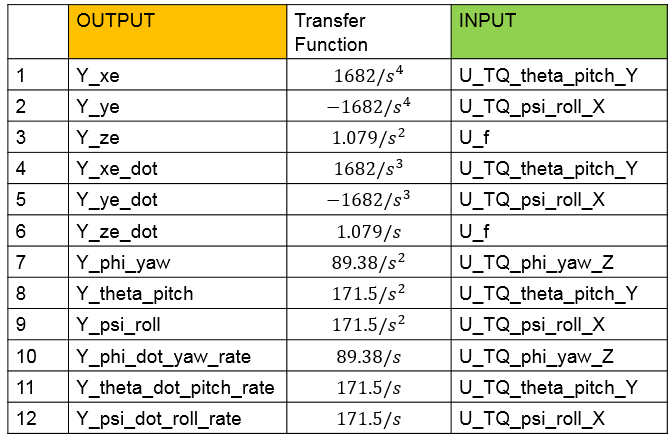

`Bradley Horton : 01-Jun-2016, bradley.horton@mathworks.com.au`

# 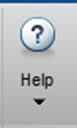 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP and try this simple text search

doc linearize control system

HINT:  today we'll be using the functions:

- `operspec`

- `findop`

- `linearize`

## Load some of the model parameters

bh_quad_params
warning('off')
% a utility
BH_MAKE_LINE = @() fprintf('\n %s', repmat('#',1,65) );

## Create the operating point specification object.

model  = 'bh_linearise_6dof_multiple_PORTS';
opspec = operspec(model);

In our operating point specification, note the following:

- Our 4 (green) root level INPORT blocks are the system inputs 

- Our 12 (orange) root level OUTPORT blocks are the system outputs 

- Our 12 STATE variable come from our 4 integrator blocks (each integrator block has 3 states)

BH_MAKE_LINE();


 #################################################################


display(opspec)


 Operating point specification for the Model bh_linearise_6dof_multiple_PORTS.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
(1.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/p,q,r 
	 spec:  dx = 0,  initial guess:             0
	 spec:  dx = 0,  initial guess:             0
	 spec:  dx = 0,  initial guess:             0
(2.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/phi theta psi
	 spec:  dx = 0,  initial guess:             0
	 spec:  dx = 0,  initial guess:             0
	 spec:  dx = 0,  initial guess:             0
(3.) 

For each of our 12 states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL 12 of our states are at SteadyState (ie: dx/dt=0)

[ opspec.States(1).SteadyState, opspec.States(2).SteadyState, opspec.States(3).SteadyState, opspec.States(4).SteadyState ]

ans =    1   1   1   1
   1   1   1   1
   1   1   1   1


Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- To maintain this steady state pose , our THRUST input needs to supply a value of 9.1.  And this makes sense as it counteracts the force appled by gravity ... which is 9.0958 (==P_veh.mass * 9.81)

- In this trimmed pose, ALL of the system outputs are ZERO.

BH_MAKE_LINE();


 #################################################################

display(opreport)


 Operating point search report for the Model bh_linearise_6dof_multiple_PORTS.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/p,q,r 
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
(2.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/phi theta psi
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
(3.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

sys_6dof_lin = linearize(model,op);

## Note the names of the system inputs and outputs

First note the names of the INPUTS "U" and the OUTPUTS "Y":

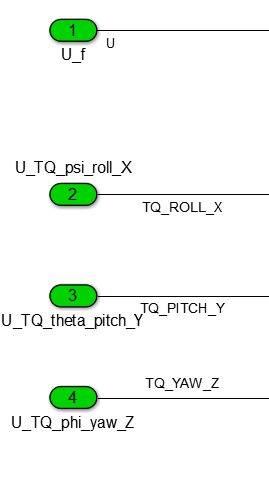           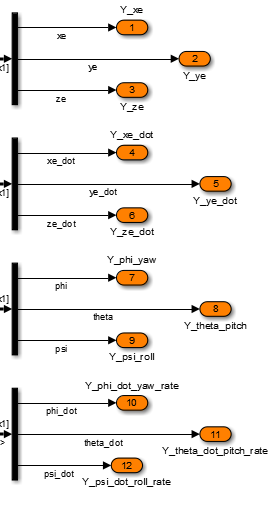

sys_6dof_lin.InputName  

ans =     'U_f'
    'U_TQ_psi_roll_X'
    'U_TQ_theta_pitch_Y'
    'U_TQ_phi_yaw_Z'



sys_6dof_lin.OutputName

ans =     'Y_xe'
    'Y_ye'
    'Y_ze'
    'Y_xe_dot'
    'Y_ye_dot'
    'Y_ze_dot'
    'Y_phi_yaw'
    'Y_theta_pitch'
    'Y_psi_roll'
    'Y_phi_dot_yaw_rate'
    'Y_theta_dot_pitch_rate'
    'Y_psi_dot_roll_rate'


So here's how we can INDEX into this:

SOME_TRANSFER_FUNCTION = tf(sys_6dof_lin('Y_theta_dot_pitch_rate', 'U_TQ_theta_pitch_Y'))


SOME_TRANSFER_FUNCTION =
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_dot_pitch_rate":
  171.5
  -----
    s
 
Continuous-time transfer function.



# OK, let's look at some transfer functions

 Pay particular attention to the following outputs:

- Y_ze_dot

- Y_phi_dot_yaw_rate

- Y_theta_dot_pitch_rate

- Y_psi_dot_roll_rate

: WHY? - because these outputs represent the outputs that we want to control.  You'll also observe that each of these outputs are caused by a single input.

## OUTPUT #1 = Y_xe

tf(sys_6dof_lin('Y_xe', :))  


ans =
 
  From input "U_f" to output "Y_xe":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_xe":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_xe":
  1682
  ----
  s^4
 
  From input "U_TQ_phi_yaw_Z" to output "Y_xe":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #2 = Y_ye

tf(sys_6dof_lin('Y_ye', :))


ans =
 
  From input "U_f" to output "Y_ye":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_ye":
  -1682
  -----
   s^4
 
  From input "U_TQ_theta_pitch_Y" to output "Y_ye":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_ye":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #3 = Y_ze

tf(sys_6dof_lin('Y_ze', :))


ans =
 
  From input "U_f" to output "Y_ze":
  1.079
  -----
   s^2
 
  From input "U_TQ_psi_roll_X" to output "Y_ze":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_ze":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_ze":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #4 = Y_xe_dot

tf(sys_6dof_lin('Y_xe_dot', :))


ans =
 
  From input "U_f" to output "Y_xe_dot":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_xe_dot":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_xe_dot":
  1682
  ----
  s^3
 
  From input "U_TQ_phi_yaw_Z" to output "Y_xe_dot":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #5 = Y_ye_dot

tf(sys_6dof_lin('Y_ye_dot', :))


ans =
 
  From input "U_f" to output "Y_ye_dot":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_ye_dot":
  -1682
  -----
   s^3
 
  From input "U_TQ_theta_pitch_Y" to output "Y_ye_dot":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_ye_dot":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #6 = Y_ze_dot

  ATTENTION: note how the **Y_ze_dot** output is only dependednt on the **U_f** input

tf(sys_6dof_lin('Y_ze_dot', :))


ans =
 
  From input "U_f" to output "Y_ze_dot":
  1.079
  -----
    s
 
  From input "U_TQ_psi_roll_X" to output "Y_ze_dot":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_ze_dot":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_ze_dot":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #7 = Y_phi_yaw

tf(sys_6dof_lin('Y_phi_yaw', :))


ans =
 
  From input "U_f" to output "Y_phi_yaw":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_phi_yaw":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_phi_yaw":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_phi_yaw":
  89.38
  -----
   s^2
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #8 = Y_theta_pitch

tf(sys_6dof_lin('Y_theta_pitch', :))


ans =
 
  From input "U_f" to output "Y_theta_pitch":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_theta_pitch":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_pitch":
  171.5
  -----
   s^2
 
  From input "U_TQ_phi_yaw_Z" to output "Y_theta_pitch":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #9 = Y_psi_roll

tf(sys_6dof_lin('Y_psi_roll', :))


ans =
 
  From input "U_f" to output "Y_psi_roll":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_psi_roll":
  171.5
  -----
   s^2
 
  From input "U_TQ_theta_pitch_Y" to output "Y_psi_roll":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_psi_roll":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #10 = Y_phi_dot_yaw_rate

  ATTENTION: note how the **Y_phi_dot_yaw_rate** output is only dependednt on the **U_TQ_phi_yaw_Z **input

tf(sys_6dof_lin('Y_phi_dot_yaw_rate', :))


ans =
 
  From input "U_f" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_phi_dot_yaw_rate":
  89.38
  -----
    s
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #11 = Y_theta_dot_pitch_rate

  ATTENTION: note how the **Y_theta_dot_pitch_rate** output is only dependednt on the **U_TQ_theta_pitch_Y **input

tf(sys_6dof_lin('Y_theta_dot_pitch_rate', :))


ans =
 
  From input "U_f" to output "Y_theta_dot_pitch_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_theta_dot_pitch_rate":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_dot_pitch_rate":
  171.5
  -----
    s
 
  From input "U_TQ_phi_yaw_Z" to output "Y_theta_dot_pitch_rate":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

## OUTPUT #12 = Y_psi_dot_roll_rate

  ATTENTION: note how the **Y_psi_dot_roll_rate** output is only dependednt on the **U_TQ_psi_roll_X **input

tf(sys_6dof_lin('Y_psi_dot_roll_rate', :))


ans =
 
  From input "U_f" to output "Y_psi_dot_roll_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_psi_dot_roll_rate":
  171.5
  -----
    s
 
  From input "U_TQ_theta_pitch_Y" to output "Y_psi_dot_roll_rate":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_psi_dot_roll_rate":
  0
 
Continuous-time transfer function.



BH_MAKE_LINE()


 #################################################################

# Where to from here ?

In the next task we're going to design 3 SISO controllers:

- Altitude (ie: Z) control

- PITCH angle control  (NB: the ROLL controller will be identical)

- YAW angle control

For each of these controllers the structure that we'll use will involve 2 proportional controllers configured in a cascade loop.  The inner loop is the velocity loop and the outer loop is the position loop. This control structure is shown below:

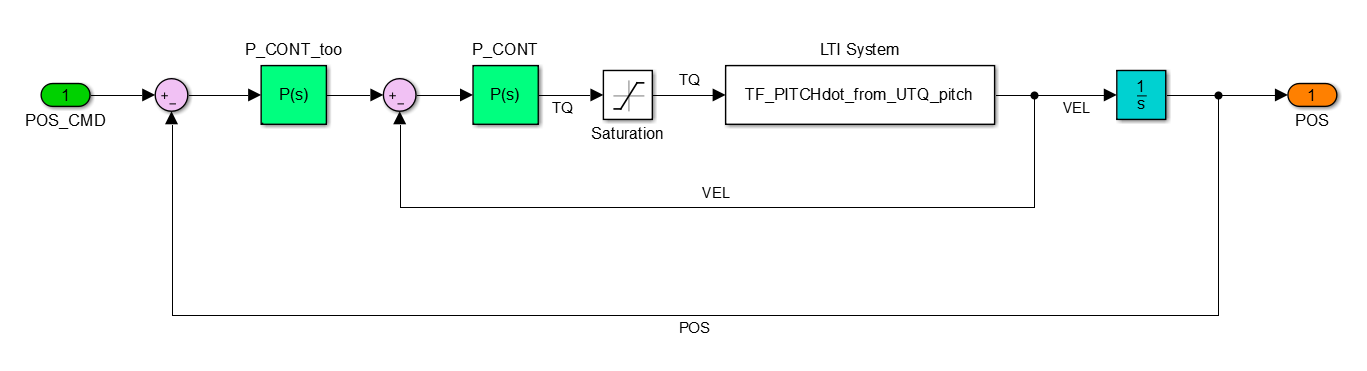

Note we can also represent this structure as:

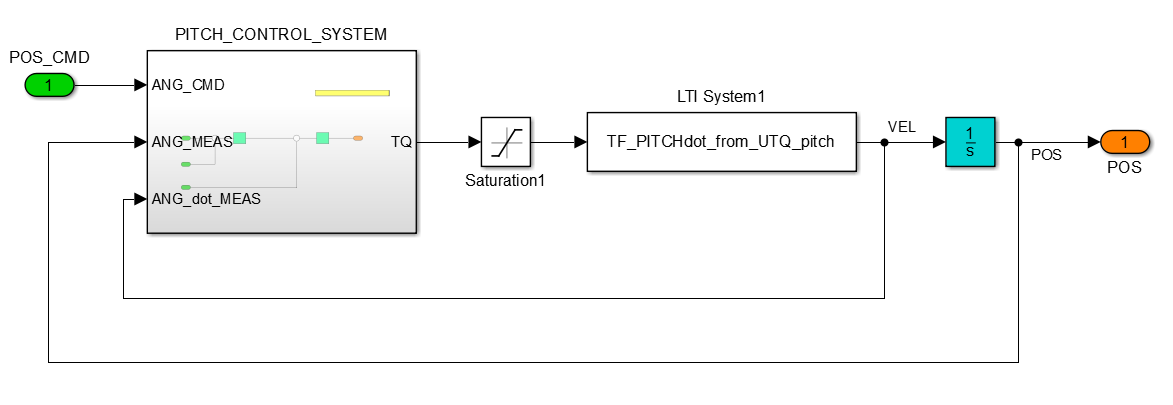

To design each controller we'll design the INNER velocity loop controller first, and then we'll design the OUTER positional controller.  The linear plants for each of these 3 control design tasks are:

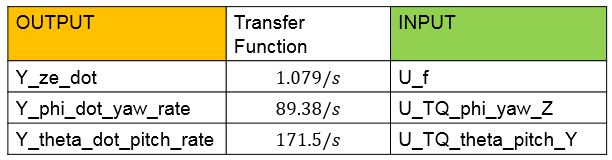

The transfer function for the **Z rate**

clc
tf(sys_6dof_lin('Y_ze_dot', 'U_f'))


ans =
 
  From input "U_f" to output "Y_ze_dot":
  1.079
  -----
    s
 
Continuous-time transfer function.



The transfer function for the **YAW rate**

tf(sys_6dof_lin('Y_phi_dot_yaw_rate', 'U_TQ_phi_yaw_Z'))


ans =
 
  From input "U_TQ_phi_yaw_Z" to output "Y_phi_dot_yaw_rate":
  89.38
  -----
    s
 
Continuous-time transfer function.



The transfer function for the **PITCH rate**

tf(sys_6dof_lin('Y_theta_dot_pitch_rate', 'U_TQ_theta_pitch_Y'))


ans =
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_dot_pitch_rate":
  171.5
  -----
    s
 
Continuous-time transfer function.

